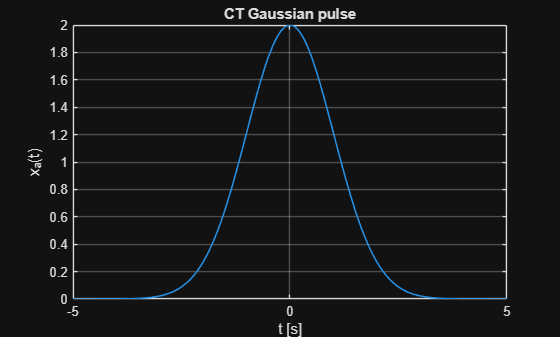

%% Week 07 – Tuesday, Exercise 1 (Q1-1, Q1-2, Q1-3)
%  DTU 62743 – FFT & fftshift intro (Week 7 Tuesday)
%  This script follows the PDF instructions step by step.

clear; close all; clc;

%% =========================
%  Q1-1: CT Gaussian + CTFT
%  -------------------------
%  Given (PDF): xa(t) = A0 * exp( - t^2 / (2*T0^2) )
%  A standard CTFT pair in Hz for this Gaussian is:
%  Xa(F) = A0 * T0 * sqrt(2*pi) * exp( - (2*pi*T0*F).^2 )

A0  = 2;          % amplitude in time
T0  = 1;          % e^-1 width in time (s)

% timeCT: -20..20 s in 0.1 s steps
timeCT = -20 : 0.1 : 20;
xa     = A0 * exp( - (timeCT.^2) / (2*T0^2) );

% freqCT: -5..5 Hz in 0.001 Hz steps
freqCT = -5 : 0.001 : 5;
Xa     = A0 * T0 * sqrt(2*pi) * exp( - (2*pi*T0*freqCT).^2 );

% plots
figure('Name','Q1-1 Time-domain Gaussian (CT)')
plot(timeCT, xa, 'LineWidth', 1.2);
xlabel('t [s]'); ylabel('x_a(t)'); title('CT Gaussian pulse');
xlim([-5 5]); grid on;

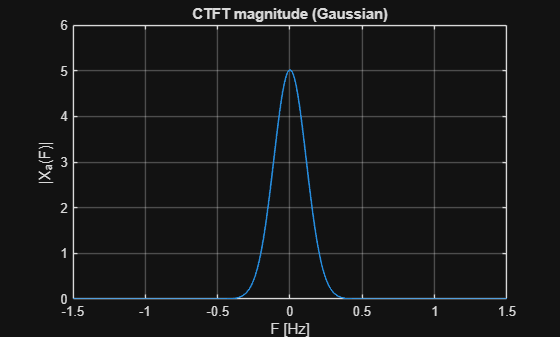


figure('Name','Q1-1 Spectrum (CTFT of Gaussian)')
plot(freqCT, Xa, 'LineWidth', 1.2);
xlabel('F [Hz]'); ylabel('|X_a(F)|'); title('CTFT magnitude (Gaussian)');
xlim([-1.5 1.5]); grid on;


%% =========================
%  Q1-2: Sample + FFT
%  -------------------
%  Sampled signal: x[n] = A0 * exp( - (( (n-0.5N)*Ts )^2) / (2*T0^2) )
%  Use PDF values: Fs=10 Hz, Ts=1/Fs, N=800. Then:
%   a) compute min/max time and peak time,
%   b) build n = 1..N,
%   c) compute x[n],
%   d) X[k] = fft(x[n]),
%   e) length(X) equals length(n)=N,
%   f) stem |X[k]| for all, 1..60, and (N-60)..N.
%  [Uge 07 – Tirsdag, Exercise 1, Q1-2] :contentReference[oaicite:2]{index=2}

Fs = 10;             % Hz
Ts = 1/Fs;           % s
N  = 800;

n  = 1:N;
tS = (n - 0.5*N) * Ts;              % time mapping from PDF

% a) min/max/peak time:
t_min = (1   - 0.5*N)*Ts;
t_max = (N   - 0.5*N)*Ts;
t_peak= (0   - 0.5*N)*Ts;           % Gaussian peaks at t=0

fprintf('Q1-2 time window: [%.3f s, %.3f s], peak around t=%.3f s\n', t_min, t_max, t_peak);

Q1-2 time window: [-39.900 s, 40.000 s], peak around t=-40.000 s


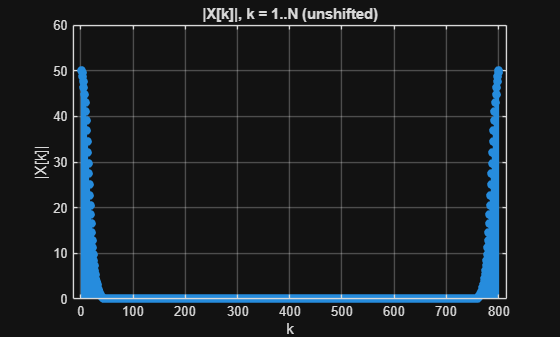


% b/c) sampled Gaussian
x = A0 * exp( - (tS.^2) / (2*T0^2) );

% d) FFT (unshifted)
X = fft(x);

% e) vector length check (should be N)
assert(length(X)==N, 'FFT length mismatch');

% f) plots (abs for magnitude)
figure('Name','Q1-2 |X[k]| – all samples (unshifted)')
stem(1:N, abs(X), 'filled'); grid on;
xlabel('k'); ylabel('|X[k]|'); title('|X[k]|, k = 1..N (unshifted)');

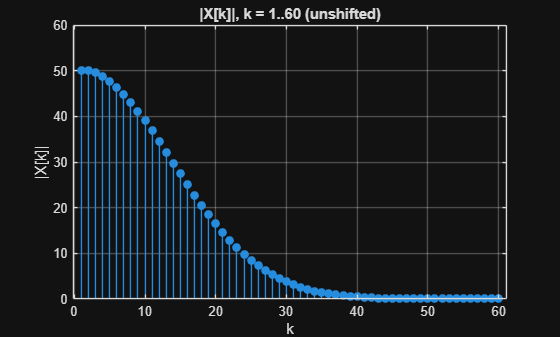


figure('Name','Q1-2 |X[k]| – zoom k=1..60 (unshifted)')
idx = 1:60;
stem(idx, abs(X(idx)), 'filled'); grid on;
xlabel('k'); ylabel('|X[k]|'); title('|X[k]|, k = 1..60 (unshifted)');

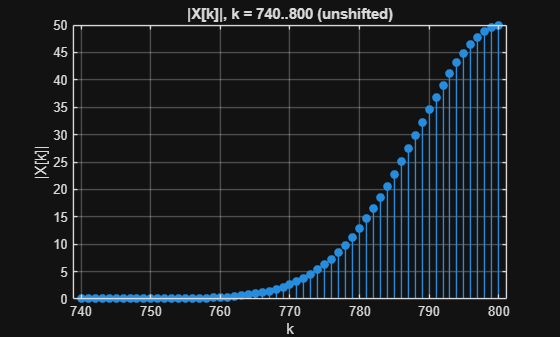


figure('Name','Q1-2 |X[k]| – zoom k=N-60..N (unshifted)')
idx2 = (N-60):N;
stem(idx2, abs(X(idx2)), 'filled'); grid on;
xlabel('k'); ylabel('|X[k]|'); title(sprintf('|X[k]|, k = %d..%d (unshifted)', N-60, N));

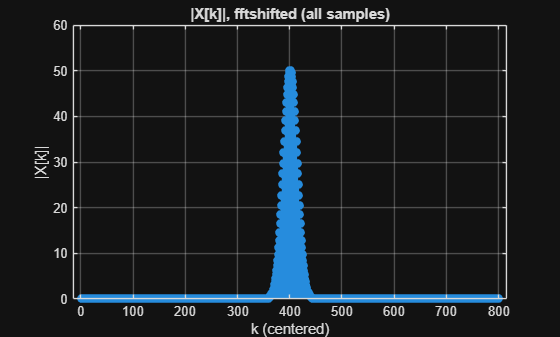


% g/h) You'll compare shape & amplitude to Q1-1 (visually, later)

%% =========================
%  Q1-3: Center with fftshift
%  --------------------------
%  Now center DC using fftshift so negative freqs are left, positive right.
%  Plot full & zoom around center.
%  [Uge 07 – Tirsdag, Exercise 1, Q1-3] :contentReference[oaicite:3]{index=3}

Xc = fftshift(X);

figure('Name','Q1-3 |X[k]| after fftshift – all samples (centered)')
stem(1:N, abs(Xc), 'filled'); grid on;
xlabel('k (centered)'); ylabel('|X[k]|'); title('|X[k]|, fftshifted (all samples)');

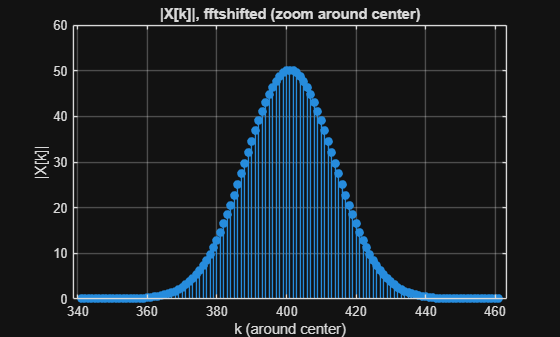


figure('Name','Q1-3 |X[k]| after fftshift – zoom around center')
mid = floor(N/2) + 1;   % center index after fftshift
rng = (mid-60):(mid+60);
stem(rng, abs(Xc(rng)), 'filled'); grid on;
xlabel('k (around center)'); ylabel('|X[k]|');
title('|X[k]|, fftshifted (zoom around center)');

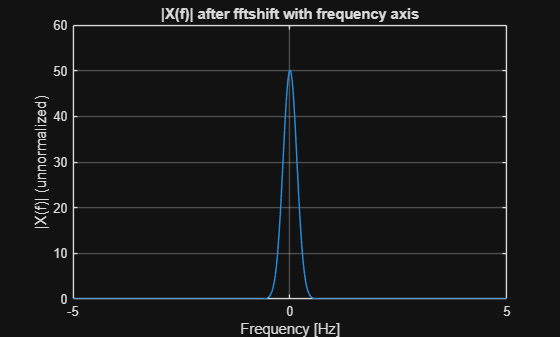


%% (Optional convenience) Frequency axis for centered spectrum
% This isn't required until later in the PDF, but it helps you reason about
% "shape vs. CTFT" now. The bin spacing is ΔF = Fs/N; range is ~[-Fs/2, Fs/2).
df   = Fs/N;
fvec = (-N/2 : N/2-1) * df;   % matches fftshifted ordering

figure('Name','Q1-3 Centered spectrum vs frequency (optional aid)')
plot(fvec, abs(Xc), 'LineWidth', 1.1); grid on;
xlabel('Frequency [Hz]'); ylabel('|X(f)| (unnormalized)');
title('|X(f)| after fftshift with frequency axis');